clc;
clear all;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


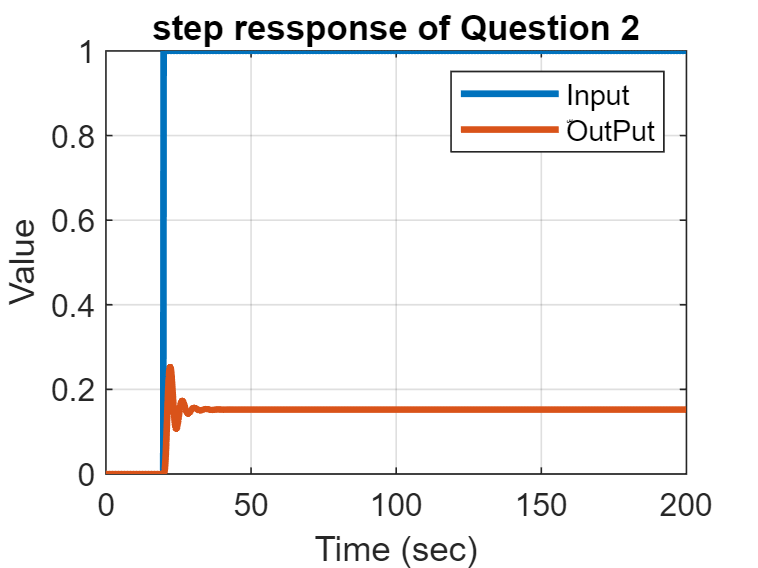

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = zeros(1,numel(t));
u(1,round(numel(t)/10,0):end)=1;
y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('step ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e4*eye(Nv) ;
phi=[];
GG=max(Parameters_in_num,Parameters_in_den)

GG = 4

Eror=zeros(1,N)

Eror =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = GG+1:N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]]';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
    

    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);%/2;
end
GG=Parameters_in_num+1

GG = 5


ident_dis = tf(theta(GG:end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
  0.0004238 z^3 + 0.002224 z^2 + 0.003485 z + 0.006651
  ----------------------------------------------------
   z^4 - 0.9858 z^3 - 0.3968 z^2 + 0.08713 z + 0.3793
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
   -0.06992 s^3 + 1.046 s^2 - 13.8 s + 119.8
  -------------------------------------------
  s^4 + 7.506 s^3 + 355.6 s^2 + 193 s + 786.2
 
Continuous-time transfer function.



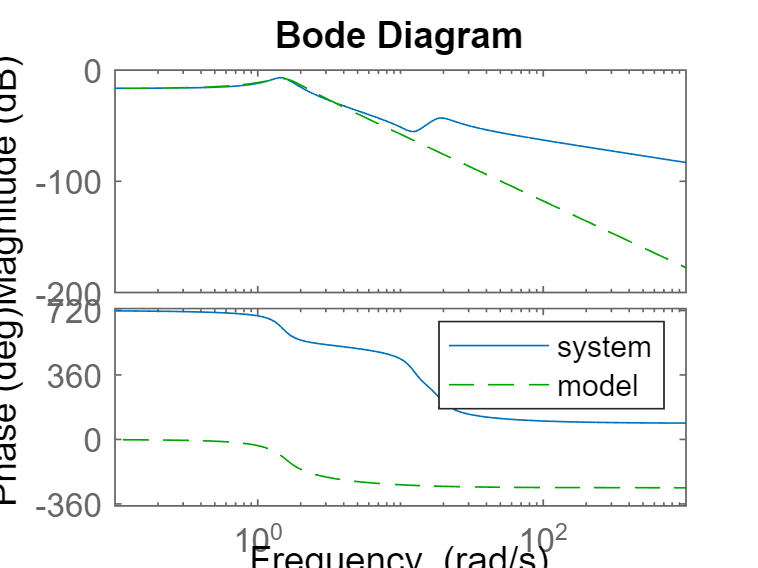

figure
bode(ident_analog ,sys,'g--' )
legend('system','model')

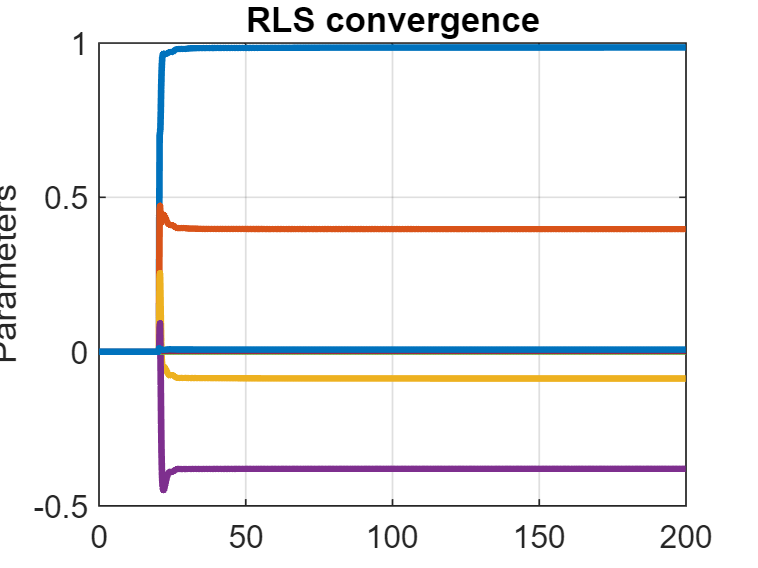


plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence') ;
grid on

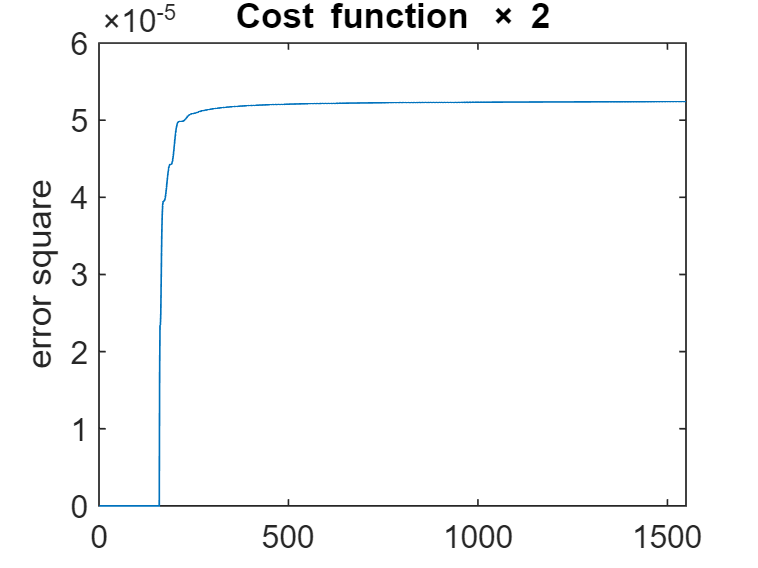

plot(Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;